# Analyse de Données - TD 3 SVM

12/12/2022

realisé en MATLAB v.R2020a.

binôme :  

- Déric Augusto França de Sales

- Michelle Ferreira Martins

close all; clear all; clc;

## 1 Génération des données linéairement séparables

### 1.1 Espace limite des observations aléatoires générées X1 e X2

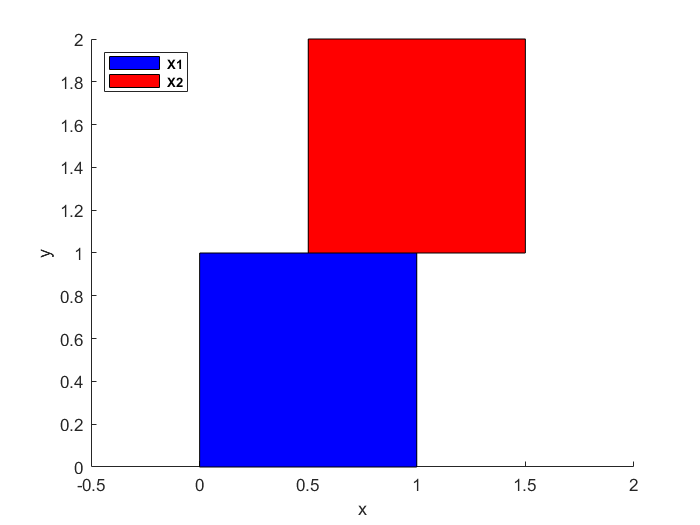

% Génération de l'image des carrés
squareX1 = [0, 1, 1, 0; 0, 0, 1, 1];
squareX2 = [0.5, 1.5, 1.5, 0.5; 1, 1, 2, 2];

patch(squareX1(1, :), squareX1(2, :), 'b')
patch(squareX2(1, :), squareX2(2, :),'r');
xlim([-0.5, 2]);
ylim([0, 2]);
legend({' X1',' X2'}, 'Location', 'northwest', 'FontSize', 8, 'FontWeight', 'bold')
xlabel('x')
ylabel('y')

### 1.2 Tracer  les donnés X1 e X2

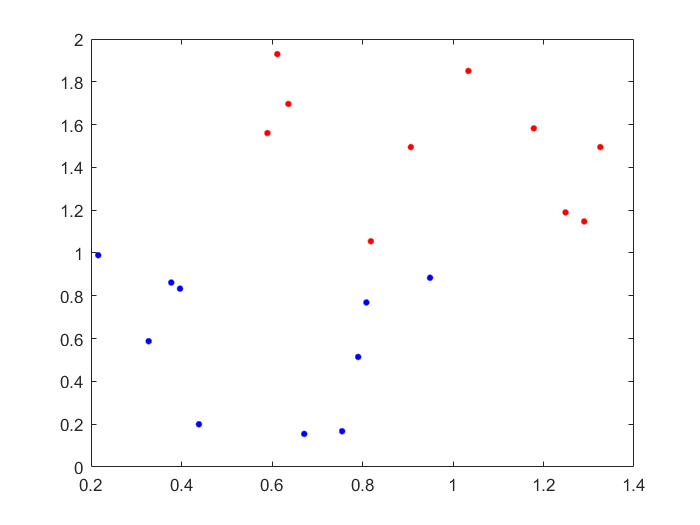

% Matrice X1 avec des valeurs variant de 0 à 1 pour les abscisses et les ordonnées
X1 = rand(10, 2);
figure
plot(X1(:, 1), X1(:, 2), 'b.', 'Markersize', 12);
hold on
% Matrice X2 avec des valeurs variant de 0,5 à 1,5 pour les abscisses et de 1 à 2 
%pour les ordonnées
X2 = [0.5 + rand(10,1), 1 + rand(10,1)];
plot(X2(:, 1), X2(:, 2), 'r.', 'Markersize', 12);

X = [X1; X2]; % Matrice 20x2
l = [ones(1,10), -ones(1, 10)]; % Vetor l

## 2 Elaboration du separateur a vaste marge

### 2.1 Construtions des matrices d'optimisation. 

Utiliser la fontion *quadprog* pour resoudre le problème d'optimisation.

% Matrices

N = 20;
p = 2;
H = eye(p);
H(:, end + 1) = 0;
H(end + 1, :) = 0;
f = zeros(1, p + 1)';
A = -[diag(l)*X, l'];
e = -ones(1, N)';

% Optimisation

[z, fval, exitflag, output, lambda] = quadprog(H,f,A,e);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% La fonction quadprog renvoie une matrice 3x1 z où les deux premières lignes sont w 
%et la troisième est la constante b
w = z(1:2);
b = z(3);

### 2.2 Tracer la separatrice

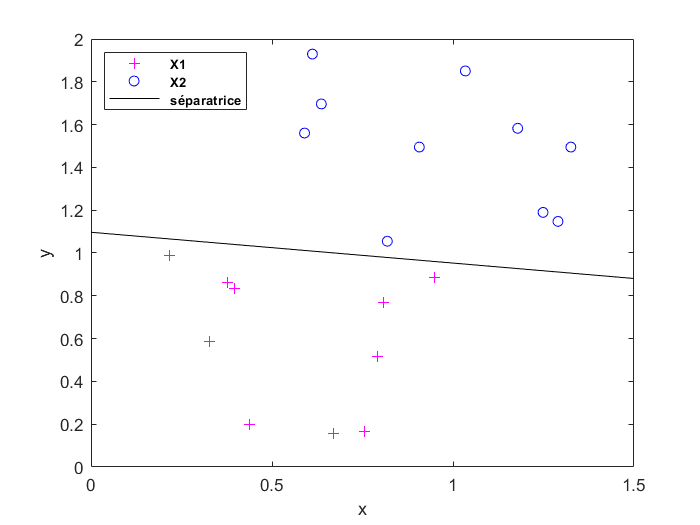

a = (w(1)/(-w(2)));
b = b/(-w(2));
y0 = a*0 + b;
y1_5 = a*1.5 + b;
droiteX = [0 1.5];
droiteY = [y0 y1_5];

figure 
plot(X(1:10,1), X(1:10,2), '+m', X(11:20,1), X(11:20,2), 'ob', droiteX, droiteY, 'k');
xlim([0, 1.5]);
ylim([0,2]);
legend({'  X1', '  X2', '  séparatrice'}, 'Location', 'northwest', 'FontSize', 8, ...
'FontWeight', 'bold')
xlabel('x')
ylabel('y')

### 2.3 Détecter les observations supports et superposer, sur la représentation graphique un marqueur supplémentaire

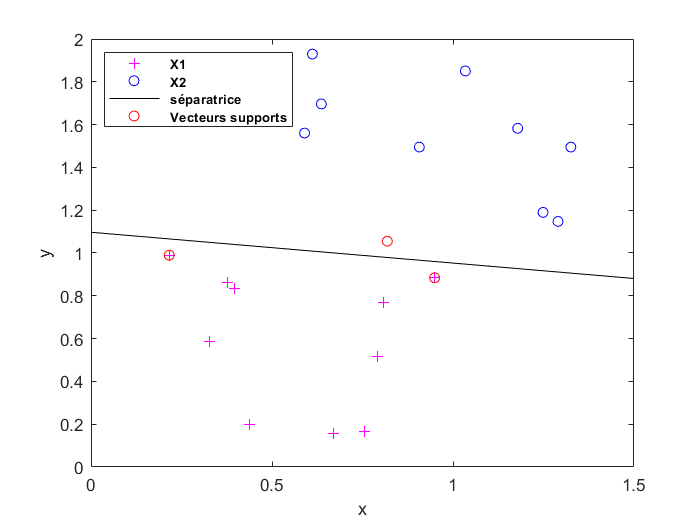

support_vector = find(lambda.ineqlin > 1e-3);
supports_points = X(support_vector(:), :);
figure
plot(X(1:10,1), X(1:10,2), '+m',  X(11:20,1), X(11:20,2), 'ob', droiteX, droiteY, ...
    'k', supports_points(:,1), supports_points(:,2), 'or');
xlim([0, 1.5]);
ylim([0,2]);
legend({'  X1', '  X2', '  séparatrice', '  Vecteurs supports'}, 'Location', ...
    'northwest', 'FontSize', 8, 'FontWeight', 'bold')
xlabel('x')
ylabel('y')

### 2.4 Déterminer l’équation des droites parallèles à la séparatrice matérialisant la marge et les tracer en pointillés. 

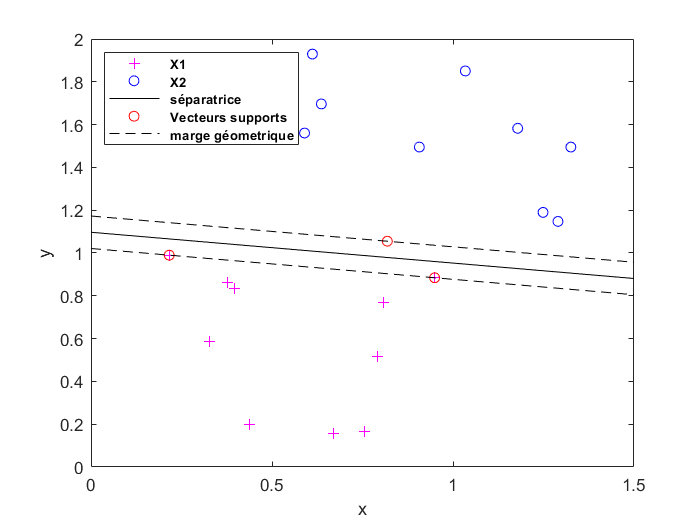

distance = 1/abs(w(2));
droiteYsup = droiteY + 1/abs(w(2));
droiteYinf = droiteY - 1/abs(w(2));
figure
plot(X(1:10,1), X(1:10,2), '+m',  X(11:20,1), X(11:20,2), 'ob', droiteX, droiteY, ...
    'k', supports_points(:,1), supports_points(:,2), 'or', droiteX, droiteYsup, ...
    '--k', droiteX, droiteYinf, '--k');
xlim([0, 1.5]);
ylim([0,2]);
legend({'  X1', '  X2', '  séparatrice', '  Vecteurs supports', ...
    '  marge géometrique'}, 'Location', 'northwest', 'FontSize', 8, ...
    'FontWeight', 'bold')
xlabel('x')
ylabel('y')

## 3 Génération des données non linéairement séparables

### 3.1 Espace limite des observations aléatoires générées X3 e X4

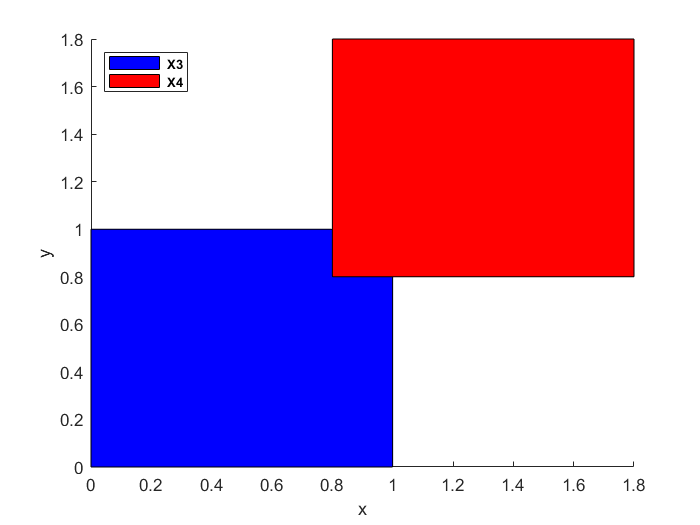

% Génération de l'image des carrés
squareX3 = [0, 1, 1, 0; 0, 0, 1, 1];
squareX4 = [0.8, 1.8, 1.8, 0.8; 0.8, 0.8, 1.8, 1.8];
figure
patch(squareX3(1, :), squareX3(2, :), 'b')
patch(squareX4(1, :), squareX4(2, :),'r');
xlim([0, 1.8]);
ylim([0, 1.8]);
legend({' X3',' X4'}, 'Location', 'northwest', 'FontSize', 8, 'FontWeight', 'bold')
xlabel('x')
ylabel('y')

### 3.2 Tracer  les donnés X3 e X4

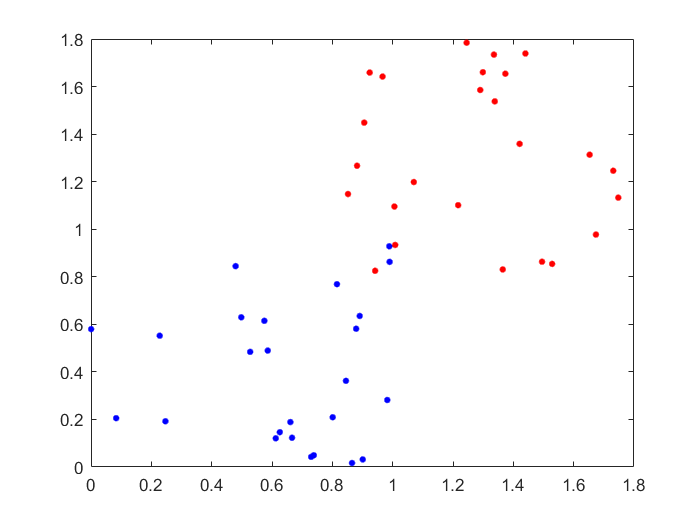

% Matrice X1 avec des valeurs variant de 0 à 1 pour les abscisses et les ordonnées
X3 = rand(25, 2);
figure
plot(X3(:, 1), X3(:, 2), 'b.', 'Markersize', 12);
hold on
% Matrice X2 avec des valeurs variant de 0,5 à 1,5 pour les abscisses et 
%de 1 à 2 pour les ordonnées
X4 = [0.8 + rand(25,1), 0.8 + rand(25,1)];
plot(X4(:, 1), X4(:, 2), 'r.', 'Markersize', 12);

## 4 Elaboration du séparateur à marge poreuse

### 4.1 Construtions des matrices d'optimisation.

X = [X3; X4]; % Matrice 50x2
l = [ones(1,25), -ones(1, 25)]; % Vetor l

% Matrices

N = 50;
p = 2;
H = eye(p);
H(:, end + 1) = 0;
H(end + 1, :) = 0;
f = zeros(1, p + 1)';
A = -[diag(l)*X, l'];
e = -ones(1, N)';

% Optimisation

[z, fval, exitflag, output, lambda] = quadprog(H,f,A,e);


No feasible solution found.

quadprog stopped because it was unable to find a point that satisfies
the constraints within the value of the constraint tolerance.

<stopping criteria details>


% La fonction quadprog renvoie une matrice 3x1 z où les deux premières lignes 
%sont w et la troisième est la constante b
w = z(1:2);
b = z(3);

### 4.2 Reprendre les questions 2 à 4 du cas des données séparables linéairement.

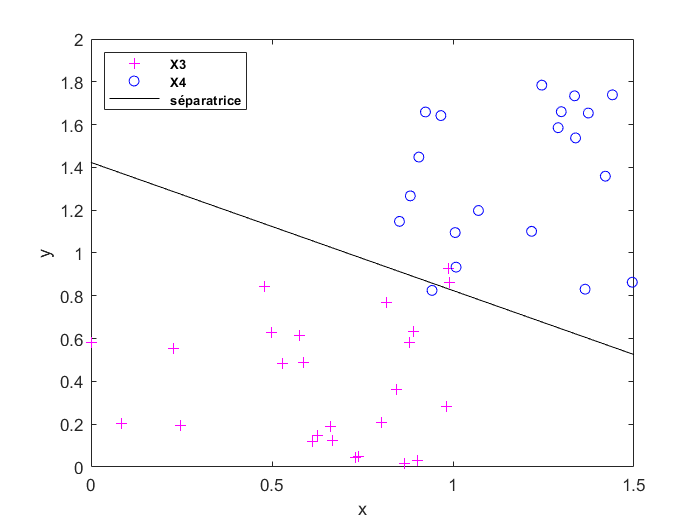

% Tracer la séparatrice

a = (w(1)/(-w(2)));
b = b/(-w(2));
y0 = a*0 + b;
y1_5 = a*1.5 + b;
droiteX = [0 1.5];
droiteY = [y0 y1_5];

figure 
plot(X(1:25,1), X(1:25,2), '+m', X(26:50,1), X(26:50,2), 'ob', droiteX, droiteY, 'k');
xlim([0, 1.5]);
ylim([0,2]);
legend({'  X3', '  X4', '  séparatrice'}, 'Location', 'northwest', 'FontSize',...
    8, 'FontWeight', 'bold')
xlabel('x')
ylabel('y')

### 4.3 Détecter les observations supports et superposer, sur la représentation graphique un marqueur supplémentaire

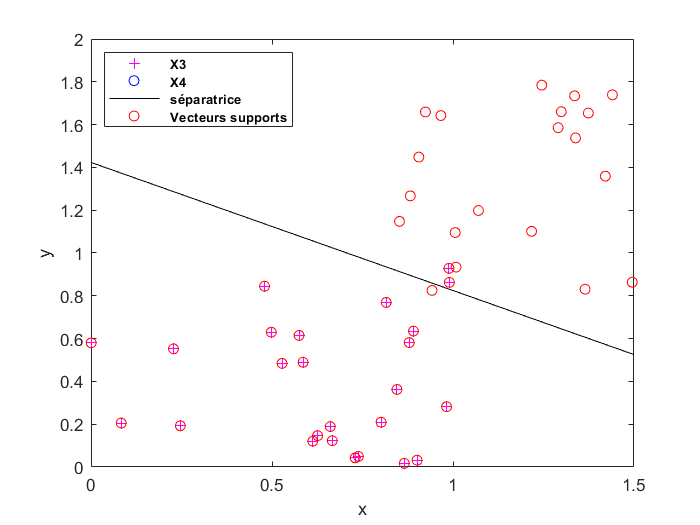

support_vector = find(lambda.ineqlin > 1e-3);
supports_points = X(support_vector(:), :);
figure
plot(X(1:25,1), X(1:25,2), '+m',  X(26:50,1), X(26:50,2), 'ob', droiteX, ...
    droiteY, 'k', supports_points(:,1), supports_points(:,2), 'or');
xlim([0, 1.5]);
ylim([0,2]);
legend({'  X3', '  X4', '  séparatrice', '  Vecteurs supports'}, 'Location', ...
    'northwest', 'FontSize', 8, 'FontWeight', 'bold')
xlabel('x')
ylabel('y')

### 4.4 Déterminer l.équation des droites parallèles à la séparatrice matérialisant la marge et les tracer en pointillés

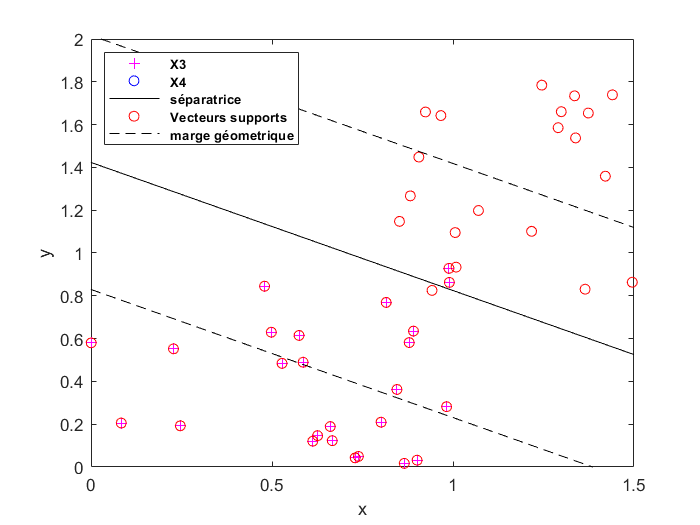

distance = 1/abs(w(2));
droiteYsup = droiteY + 1/abs(w(2));
droiteYinf = droiteY - 1/abs(w(2));
figure
plot(X(1:25,1), X(1:25,2), '+m',  X(26:50,1), X(26:50,2), 'ob', droiteX, droiteY,...
    'k', supports_points(:,1), supports_points(:,2), 'or', droiteX, droiteYsup, ...
    '--k', droiteX, droiteYinf, '--k');
xlim([0, 1.5]);
ylim([0,2]);
legend({'  X3', '  X4', '  séparatrice', '  Vecteurs supports', ...
    '  marge géometrique'}, 'Location', 'northwest', 'FontSize', 8, ...
    'FontWeight', 'bold')
xlabel('x')
ylabel('y')